# HW 6 

## Prob. 10.1 a - c

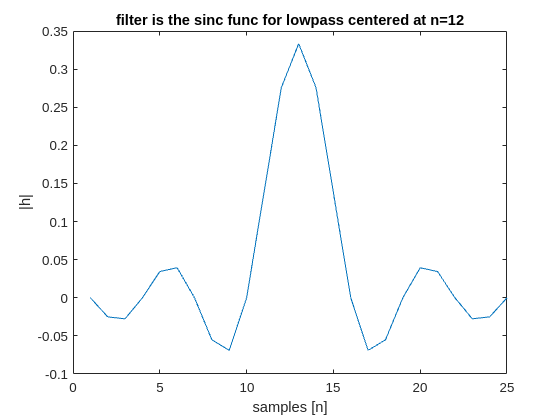

N = 25;
n = linspace(0,N-1,N);
h = @(n,N,w) sinc((n-(N-1)/2).*w).*w;
rec = ones(1,N);
figure
plot(h(n,N,1/3))
title(sprintf("filter is the sinc func for lowpass centered at n=%d",(N-1)/2))
xlabel("samples [n]")
ylabel("|h|")

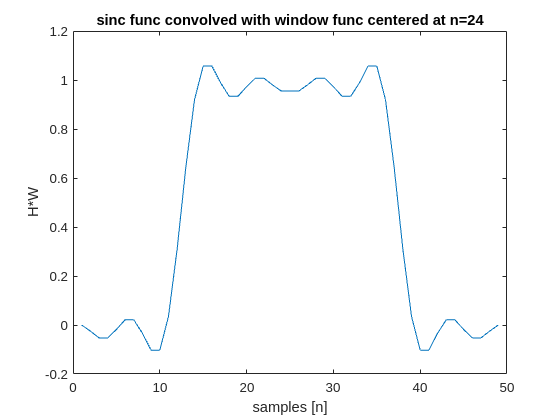

plot(conv(h(n,N,1/3),rec));
title(sprintf("sinc func convolved with window func centered at n=%d",(2*(N-1))/2))
xlabel("samples [n]")
ylabel("H*W")

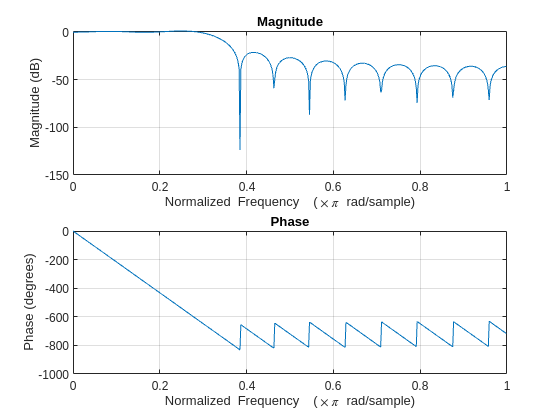

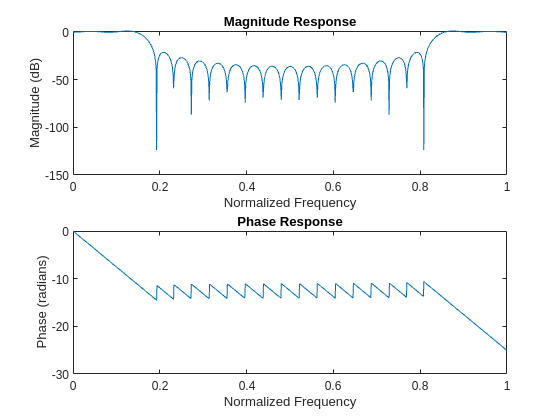

% the goal for my version
freqz(h(n,N,1/3))
[mag, phase] = getresponse(h_actual,1024);

Not sure were I went wrong, but mine seems squashed compared to the version by freqz. mine seems like it should end at .5 given the results, so there may be a factor of two sneaking in somewhere.

## c) hamming window

using all the same stuff I used above, I create the hamming window of length 25 to set up the lpf made above with the new window. 

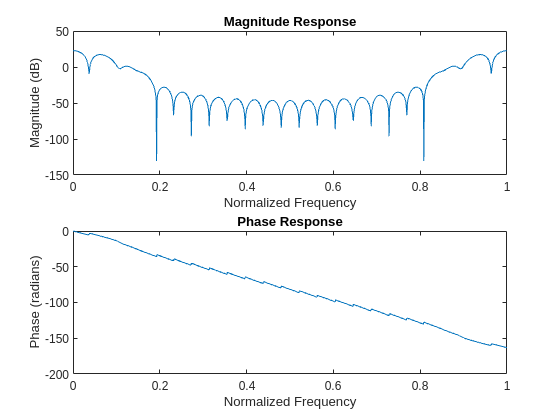

figure
hamming_window = @(n,M) 0.54 - 0.46*cos(2*pi*n/(M - 1));
hamming_h = conv(h(n,N,1/3),hamming_window(n,15));
getresponse(hamming_h,1024);

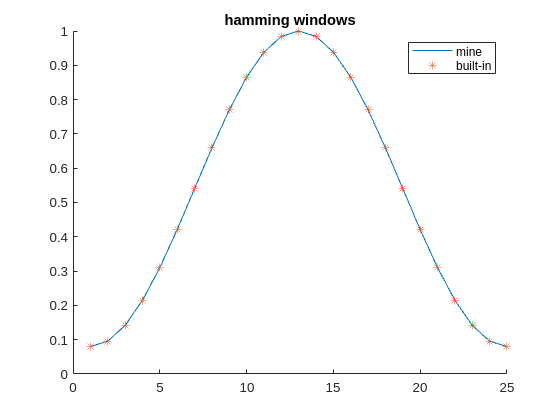

figure
N = 25;
hold on
plot(hamming_window(n,N))
plot(hamming(N),'*')
title('hamming windows')
legend(["mine","built-in"])
hold off

This was to show that the results agree with the expectation of the hamming window using the hamming expression

## Prob 10.6

Determine the coefficients {h(n)} of a linear-phase FIR filter of length M = 15 which has a symmetric unit sample response and a frequency response that satisfies the condition:


$$H_r \left(\frac{2\pi k}{15}\right)=\left\lbrace \begin{array}{ll}
1 & k=0:3\\
0 & x=4:7
\end{array}\right.$$


broken implementation here. it does not seem to work, but it was an effort to make it as close to a one-liner as I could get.

% N = 15;
% H = @(k) (h(0:1:N,N,2.*k/N));
% k = linspace(0,7,8);
%HH = arrayfun(H,k,UniformOutput=false);figure;%res = H(k);

Index in position 1 is invalid. Array indices must be positive integers or logical values.

Error in hw6>@(k)(h(0:1:N,N,2.*k/N)) (line 30)
H = @(k) (h(0:1:N,N,2.*k/N));

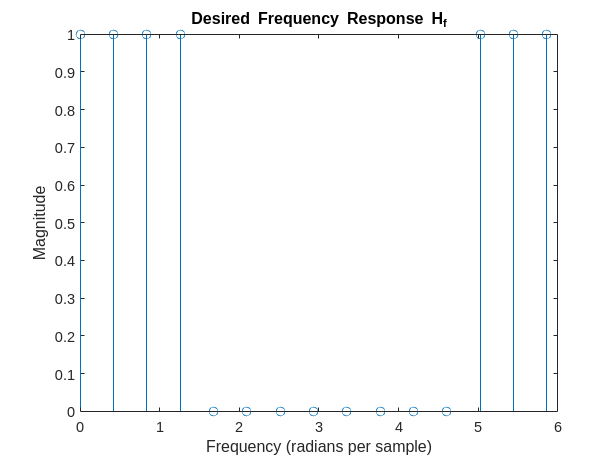

% Define the length of the filter
M = 15;

% Define the frequency response Hf for k = 0 to 7
Hf = zeros(1, M);
Hf(1:4) = 1;  % k = 0:3

% Since the filter is real-valued, the frequency response is symmetric about the Nyquist frequency
% This symmetry implies Hf(15-k) = Hf(k) for k = 0:7
Hf(M-2:M) = Hf(2:4);

% Define the frequency bins
k = 0:M-1;

% Frequency vector for plotting
f = (2 * pi / M) * k;

% Plot the frequency response
stem(f, Hf);

xlabel('Frequency (radians per sample)');
ylabel('Magnitude');
title('Desired Frequency Response H_f');

Hf

Hf =      1     1     1     1     0     0     0     0     0     0     0     0     1     1     1


I was able to get it correct using the ifft version, but my implementation does not do it correctly

% Desired frequency response for k = 0 to 7
Hf = [1 1 1 1 0 0 0 0];

% Length of the filter
M = 15;

% Since the response is symmetric and real, we complete the second half as a mirror of the first
% (excluding the last value since it's the Nyquist frequency and should not be doubled)
Hf = [Hf, fliplr(Hf(2:end))];

% Apply the inverse DFT to get the impulse response
h = real(ifft(Hf));

% Due to numerical precision, there might be a tiny imaginary part, so we take only the real part
h = real(h);

% The resulting vector h contains the filter coefficients
h

h =     0.4667    0.3189    0.0341   -0.1079   -0.0365    0.0667    0.0412   -0.0498   -0.0498    0.0412    0.0667   -0.0365   -0.1079    0.0341    0.3189


function [magnitude,phase] = getresponse(h_actual, N_fft)

% Number of points for DFT N_fft 
% Frequency vector for DFT computation
f = linspace(0, 1, N_fft);
% Time index vector
n = 0:length(h_actual) - 1;
% Frequency index vector
k = 0:N_fft - 1;
% Create the matrix for exponential terms
[n_matrix, k_matrix] = meshgrid(n, k);
exponential_matrix = exp(-1j * 2 * pi * n_matrix .* k_matrix / N_fft);
% Multiply filter coefficients and sum
H = sum(h_actual .* exponential_matrix, 2);
% Calculate the magnitude and phase
magnitude = abs(H);
phase = unwrap(angle(H));  % unwrap is used to make the phase plot continuous
% Plot the magnitude response
subplot(2,1,1);
plot(f, 20*log10(magnitude));  % Magnitude in dB
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
title('Magnitude Response');
% Plot the phase response
subplot(2,1,2);
plot(f, phase);
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
title('Phase Response');
end